# Master Stiffness Matrix and Body Load Vector for the Timoshenko beam using Page-Wise Computations and `sparse`-Matrices

Computation of the master stiffness matrix and master load vector corresponding to the standard Timoshenko beam formulation with three degrees of freedom per node $\left(w,\beta \right)$, the vertical deflection and beam's cross-sectional rotation, respectively, using [page-wise](https://blogs.mathworks.com/loren/2021/01/14/paged-matrix-functions/) computation of the element stiffness matrices [`sparse`](https://www.mathworks.com/help/matlab/ref/sparse.html)-matrices for the assembly. A schematic of this workflow is shown in the following figure:

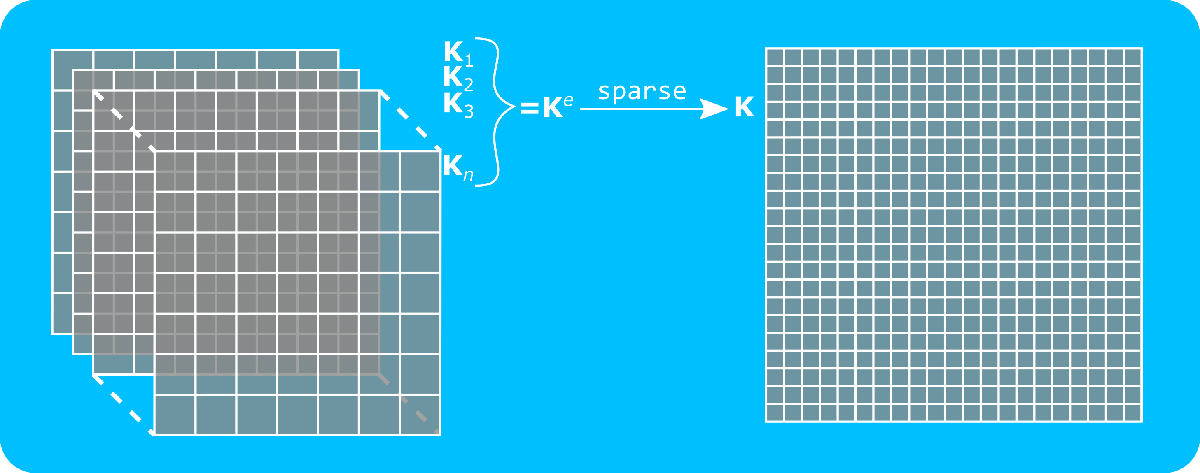

The master stiffness matrix and master load vector for the standard Timoshenko beam are given by the following relations:


$$\begin{array}{ll}
\mathbf{K} = \int_{L} \mathbf{B}_{\text{s}}^{\text{T}} \mathbf{C}_{\text{s}} \mathbf{B}_{\text{s}} \, \text{d} L+ \int_{L} \mathbf{B}_{\text{b}}^{\text{T}} \mathbf{C}_{\text{b}} \mathbf{B}_{\text{b}} \: \text{d} L , & \text{(1.1)} \\
\mathbf{F} = \int_{L} \mathbf{N}^{\text{T}} \left[ \begin{array}{c} \bar{p} \\ \bar{m} \end{array} \right] \: \text{d} L + \left[\mathbf{N}^{\text{T}} \left[ \begin{array}{c} \bar{P} \\ \bar{M} \end{array} \right]  \right]_0^{L}. & \text{(1.2)}
\end{array}$$


function [K, F, invHG] = computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
    (msh, ~, computeBasisFunctionsAndDerivsU, ~, propStr)

## **Function Description**

Computation of the master stiffness matrix and the master load vector for a plate using the two-dimensional Reissner-Mindlin plate theory with three degrees of freedom per node $\left(w,\beta \right)$, the vertical deflection and the cross-sectional rotation of the beam using a page-wise computation for the element stiffness matrices and subsequently `sparse`-matrices for the assembly.

                                                          **Input** :

                                                             `msh` : Structure containing the nodes and the elements in a quadrilateral finite element mesh

                                                                        ` .nodes` : Array with the nodal coordinates in the finite element mesh

                                                                  ` .elements` : Array with the nodal numbering per element in the finite element mesh

                  `computeElStiffMtxForceVct` : Function handle to the computation of the element stiffness matrix of the Timoshenko beam element

      `computeBasisFunctionsAndDerivsU` : Function handle to the computation of the basis functions and their derivatives for the pair of primal unknown fields $\left( w, \beta \right)$

`computeBasisFunctionsAndDerivsBeta` : Function handle to the computation of the basis functions and their derivatives for the pair of the secondary unknown fields $\left( Q, M \right)$ - Only needed for the Hellinger-Reissner formulation of the Timoshenko beam

                                                    `propStr` : MATLAB®-struct containing the following fields:

                                                                           `.t` : Thickness

                                                                           `.b` : Width

                                                                           `.A` : Cross sectional area of the beam

                                                                     `.qBar` : Distributed load on the beam

                                                                     `.mBar` : Distributed moment on the beam

                                                                           `.E` : Young's modulus

                                                                         `.nu` : Poisson's ratio

                                                                           `.I` : Moment of inertia

                                                                          `.G` : Shear modulus

                                                                  `.alpha` : Shear correction factor

                                                       **Output** :

                                                                 `K` : Master stiffness matrix of a Timoshenko beam (`sparse`)

                                                                 `F` : Master force vector of a Timoshenko beam (sparse)

                                                         `invHG` : Dummy output

## **Function Implementation**

### Argument validation

    arguments
        msh (1,1) struct {mustHaveNodesAndElements}
        ~
        computeBasisFunctionsAndDerivsU (1,1) function_handle
        ~
        propStr (1,1) struct {mustHaveTimoshenkoBeamProperties}
    end

### Read input

    numDOFsPerNode = 2; % one vertical displacement and one cross-sectional rotation
    numNodes = height(msh.nodes);
    numDOFs = numNodes*numDOFsPerNode;
    numEl = height(msh.elements);
    numNodesEl = width(msh.elements);
    numDOFsEl = numDOFsPerNode*numNodesEl;
    nodesElPagewise = msh.nodes(msh.elements);
    invHG = 'undefined'; % needed only for the Hellinger-Reissner formulation

### Initialization of the page-wise element stiffness matrices and load vectors

    KePageWise = zeros(numDOFsEl, numDOFsEl, numEl);
    FePageWise = zeros(numDOFsEl, 1, numEl);

### Construction of the page-wise Element Freedom Tables (EFTs)

    EFT = squeeze(reshape(vertcat(2*reshape(transpose(msh.elements), 1, numNodesEl, numEl)-1, ...
        2*reshape(transpose(msh.elements), 1, numNodesEl, numEl)), numDOFsEl, 1, numEl));

### Construction of the page-wise material matrices

    C = [propStr.alpha*propStr.G*propStr.A 0
         0                                 propStr.E*propStr.I];
    CPageWise = repmat(C, 1, 1, numEl);

### Gauss points and weights for the numerical integration

    numGP = width(msh.elements);
    [xiGP, GWxi] = getGaussPointsAndWeightsOverUnitDomain(numGP);

### Loop over all the Gauss points for the numerical integration

    for iGP = 1:numGP

#### Basis functions at the Gauss point

        dN = computeBasisFunctionsAndDerivsU(xiGP(iGP));
        numBF = height(dN);
        if numBF ~= numNodesEl
            error("Numner of nodes does not match the number of basis functions");
        end
        dN_pagewise = repmat(dN, 1, 1, numEl);

#### Pagewise basis functions' matrix


$$\mathbf{N} = \left[ \begin{array}{ccccc} N_1(\xi) & 0 & \cdots &  N_n(\xi) & 0 \\ 0 & N_1(\xi) & \cdots &  0 & N_n(\xi) \end{array} \right]$$


        NmtxPageWise = zeros(2, numDOFsEl, numEl);
        NmtxPageWise(1, 2*(1:numNodesEl) - 1, :) = dN_pagewise(1:numNodesEl, 1, :);
        NmtxPageWise(2, 2*(1:numNodesEl), :) = dN_pagewise(1:numNodesEl, 1, :);

#### Page-wise Jacobian matrix

        JacobianMtxPagewise = pagemtimes(dN_pagewise(:, 2, :), 'transpose', ...
            reshape(transpose(nodesElPagewise), numBF, 1, numEl), 'none');

#### Page-wise basis functions' derivatives with respect to the physical space

        dNdXPageWise = pagetranspose(pagemldivide(JacobianMtxPagewise, pagetranspose(dN_pagewise(:, 2, :))));

#### Page-wise B-operator matrix

        BmtxPageWise = zeros(2, numDOFsEl, numEl);
        BmtxPageWise(1, 2*(1:numNodesEl) - 1, :) = dNdXPageWise(1:numNodesEl, 1, :);
        BmtxPageWise(1, 2*(1:numNodesEl), :) = dN_pagewise(1:numNodesEl, 1, :);
        BmtxPageWise(2, 2*(1:numNodesEl), :) = dNdXPageWise(1:numNodesEl, 1, :);

#### Computation of the element stiffness matrices and element load vectors through page-wise computations

        KePageWise = KePageWise + ...
            pagemtimes(pagemtimes(pagemtimes(BmtxPageWise, 'transpose', CPageWise, 'none'), ...
            BmtxPageWise), JacobianMtxPagewise)*GWxi(iGP);
        FePageWise = FePageWise + ...
            pagemtimes(pagemtimes(NmtxPageWise, 'transpose', ...
            repmat([propStr.qBar; propStr.mBar], 1, 1, numEl), 'none'), ...
            JacobianMtxPagewise)*GWxi(iGP);

    end

### Assembly to the master stiffness matrix and consistent nodal force vector using [`sparse`](https://www.mathworks.com/help/matlab/ref/sparse.html)-matrices

[K, F] = assembleSparseMatrices(EFT, numDOFs, numDOFsEl, numEl, KePageWise, FePageWise);

end